# CREATE-NL electromagnetic model

## Load model

Let's start by setting our path

addpath ./functions
addpath ./data

and loading an electromagnetic model of our tokamak (here we use JT60-SA)

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat'); % specify model's path
model = load(modelName); % load model variables into a structure

Our model file contains quite a few variables

model

model = struct with fields:
      Input_struct: [1×1 struct]
    preproc_struct: [1×1 struct]
             xd_np: [143×1 double]
              y_np: [2626×1 double]
              x_np: [18462×1 double]
            y_type: {2626×3 cell}
                 C: [2626×140 double]
                 F: [2626×2 double]
                LE: [140×2 double]
                 L: [140×140 double]
                 R: [140×140 double]
            CIcirc: [139×140 double]
              CIpl: [1.1125e-12 -2.4757e-13 -2.9222e-13 5.5206e-13 7.5439e-13 6.0744e-13 -1.9455e-13 -7.9485e-13 -6.8190e-13 -4.3127e-12 3.5495e-13 -1.2321e-12 1.8204e-14 4.1190e-14 1.3554e-14 4.3781e-14 4.6505e-14 1.7121e-14 -1.4977e-14 -1.2169e-14 … ]


In particular

- **C, CIcirc, CIpl, F, L, LE, R** are *matrices* used for the linearized model;

- **Input_struct, preproc_struct** are *data structures* used by CREATE-NL;

- **x_np** is the *state vector *(flux in the FEM nodes + currents);

- **xd_np** contains the equilibrium currents (again!) and some parameters related to the internal plasma current profile (we won't use it);

- **y_np** is the *output vector*, containing the equilibrium values of the linear model outputs, obtained as a post-processing of the equilibrium poloidal flux map;

- **y_type** are the output *names and indexes *associated to the values contained in y_np.

The indexes in y_type can be used to extract the model's outputs. For instance, to extract the plasma boundary flux (we'll need it later):

i_psb = get_y_idx(model.y_type,'psb_c');
psib  = model.y_np(i_psb) % in Wb/rad

psib = -0.0201

Let's have a look at our equilibrium. We start by plotting the FEM mesh and a few magnetic surfaces, contained in CREATE-NL input structure (CREATE-NL makes use of Matlab's PDE-toolbox; if you take a look, you will find the toolbox commands buried in the plot functions)

nnodes = size(model.Input_struct.p,2); % no. of FEM nodes
psieq  = model.x_np(1:nnodes);

figure
plot_mesh(model.Input_struct);
hold on
plot_plasma(model.Input_struct, psieq, 50);

and then we add the plasma boundary

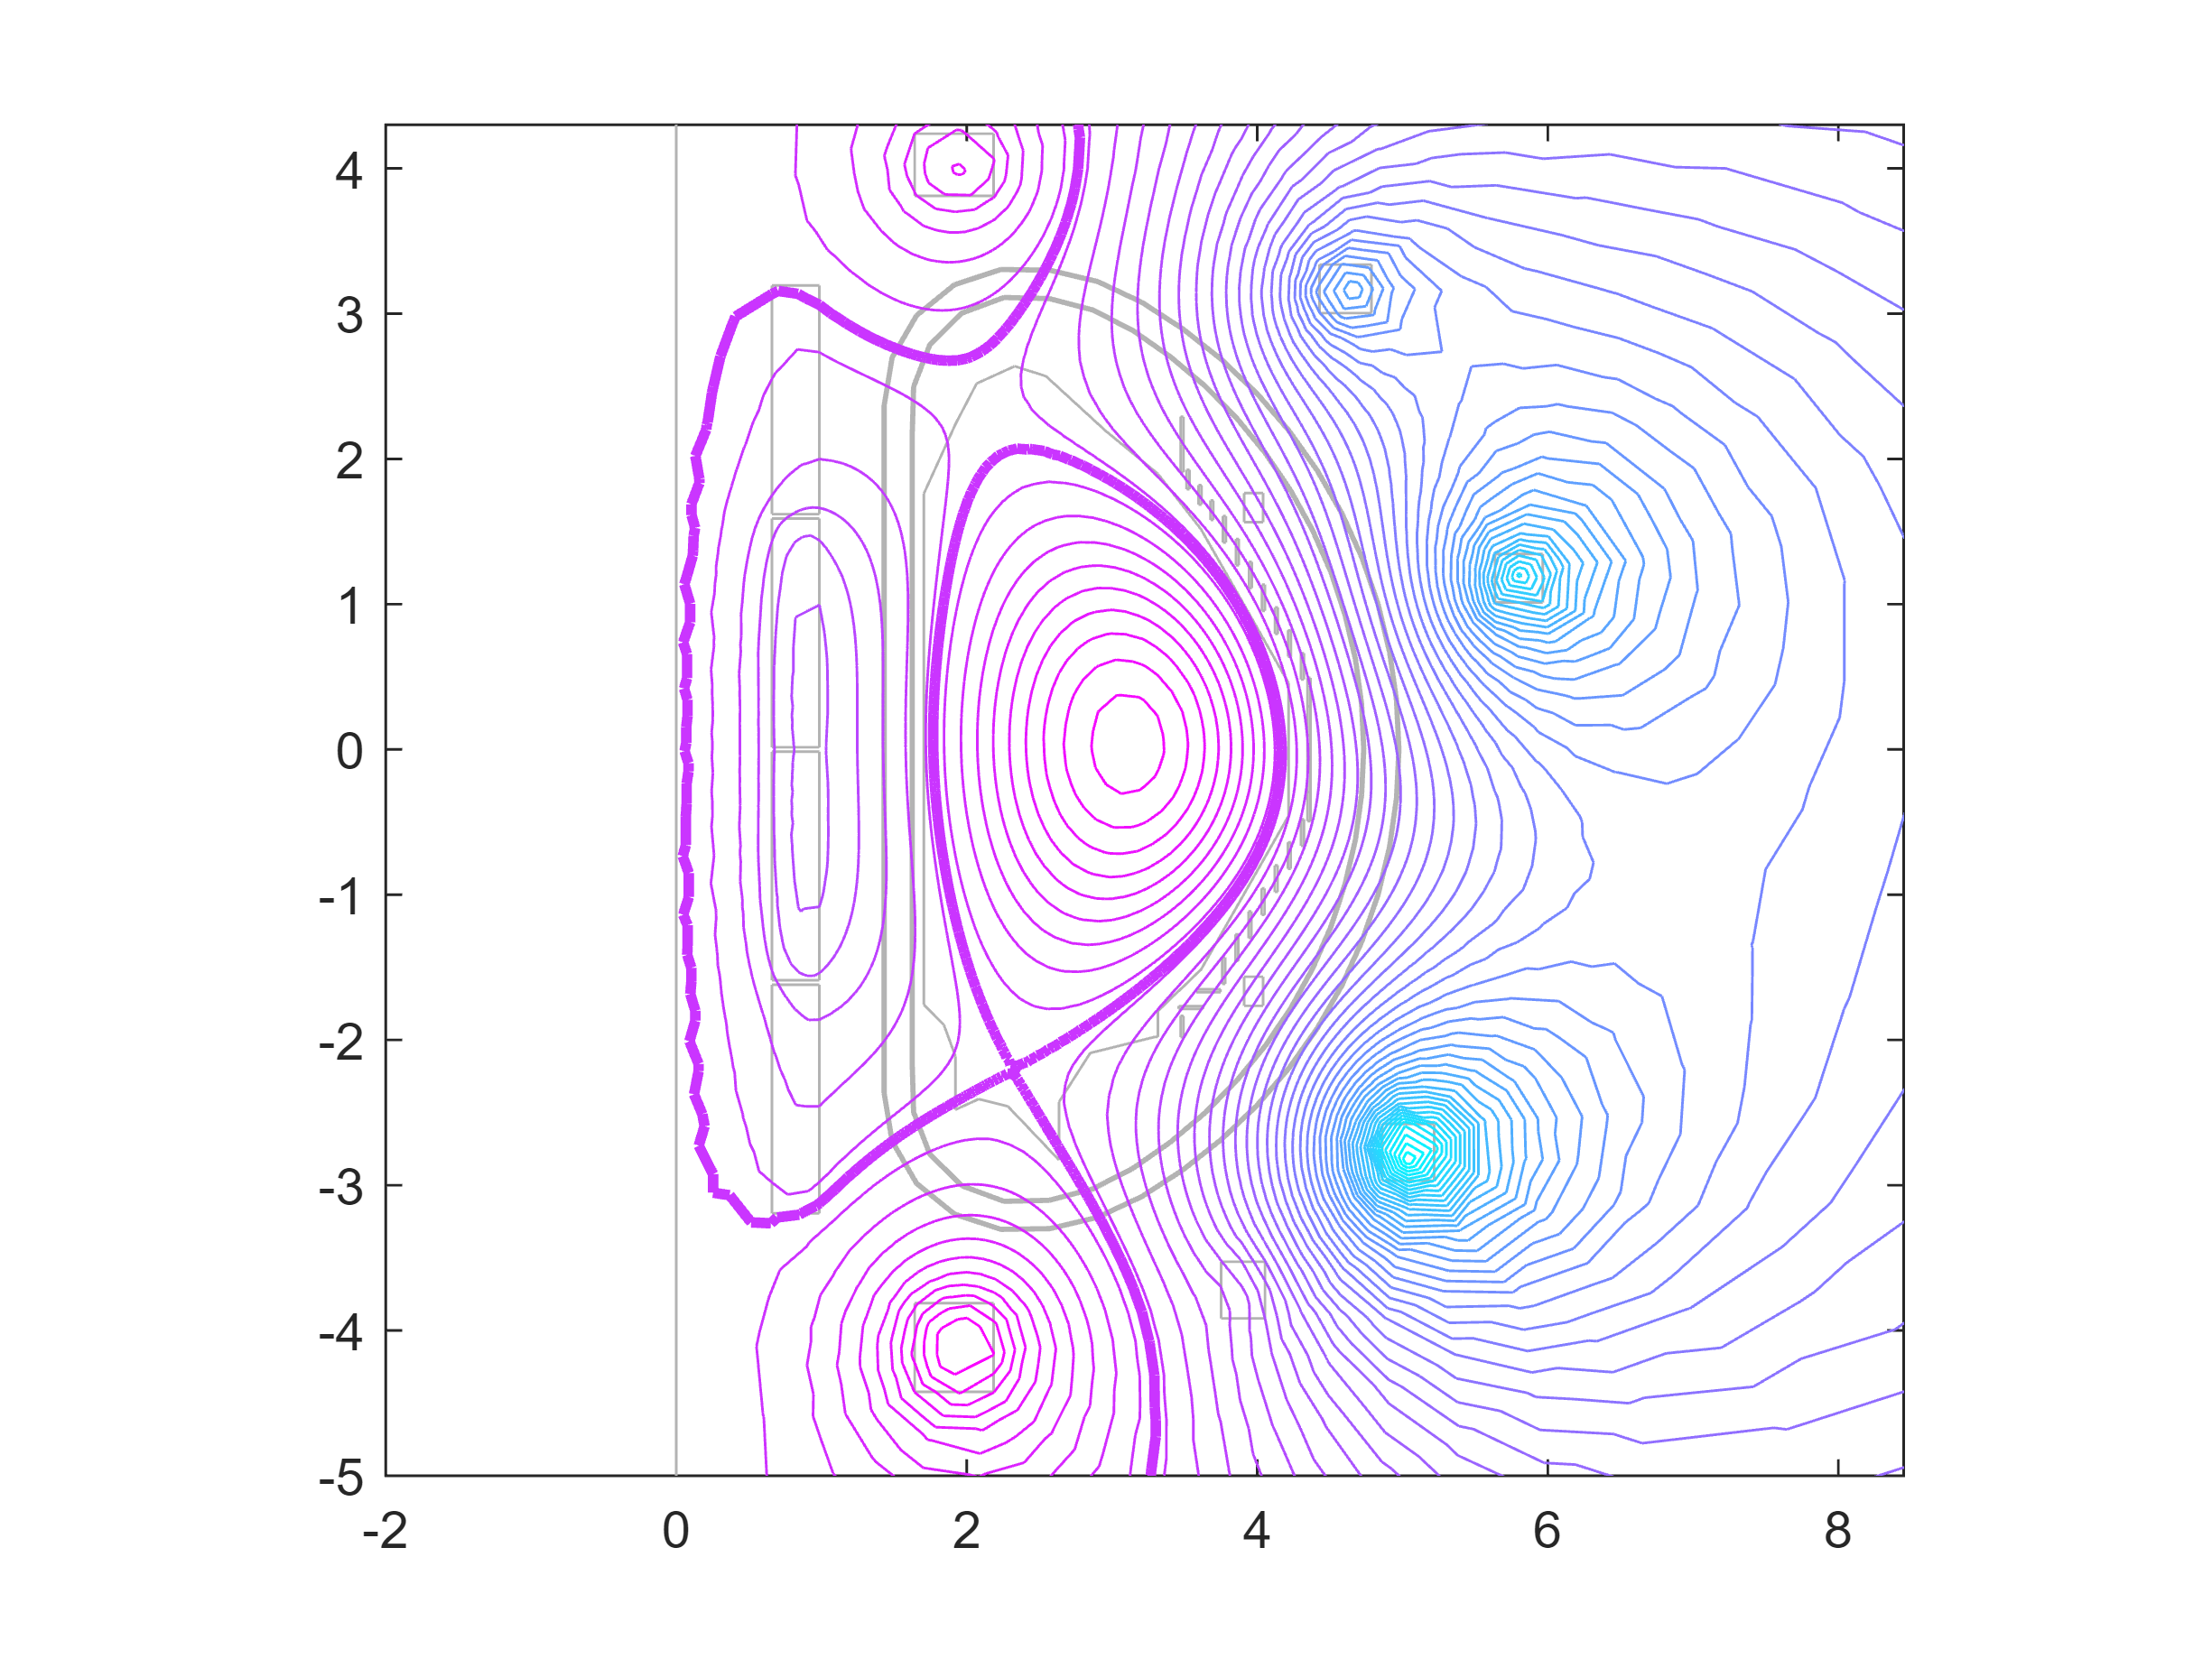

hb = plot_plasma(model.Input_struct,psieq,psib*[1 1]);
set(hb,'linewidth',2); % make boundary fatter
xlim([-2.00 8.45])
ylim([-5.00 4.30])

## Linearized model

We are now ready to extract the plasma *linearized response model *that we'll use to design our controllers. We describe our tokamak (around the considered equilibrium configuration) by means of the following circuit equations


$$L \delta \dot{I}(t) + LE \delta \dot{w}(t)= -R \delta I (t) + S\delta V(t)$$



$$\delta y(t) = C \delta I(t) + D \delta V(t) + F \delta w(t)$$


where

- L is the inductance matrix, modified by the presence of the plasma

- R is the (diagonal) resistance matrix

- S is a polarity matrix (usually the identity matrix)

- LE is a matrix which is used to take into account the effect of the disturbance variations on the currents

- y is the output vector

- C, D, F are obtained from the linearization procedure

The model can be recast in standard I-S-U form by putting $x:=\delta I$ and setting

- 
$$A = -L^{-1}R$$


- 
$$B = L^{-1}S$$


- 
$$E = -L^{-1}LE$$


The linearized model can be used to predict 

- how the voltage applied to the coils will influence the evolution of the currents

- how a variation of the currents will influence a set of outputs of interests

In this example, a grid of virtual flux sensors has been added to the outputs, placed all over the chamber.

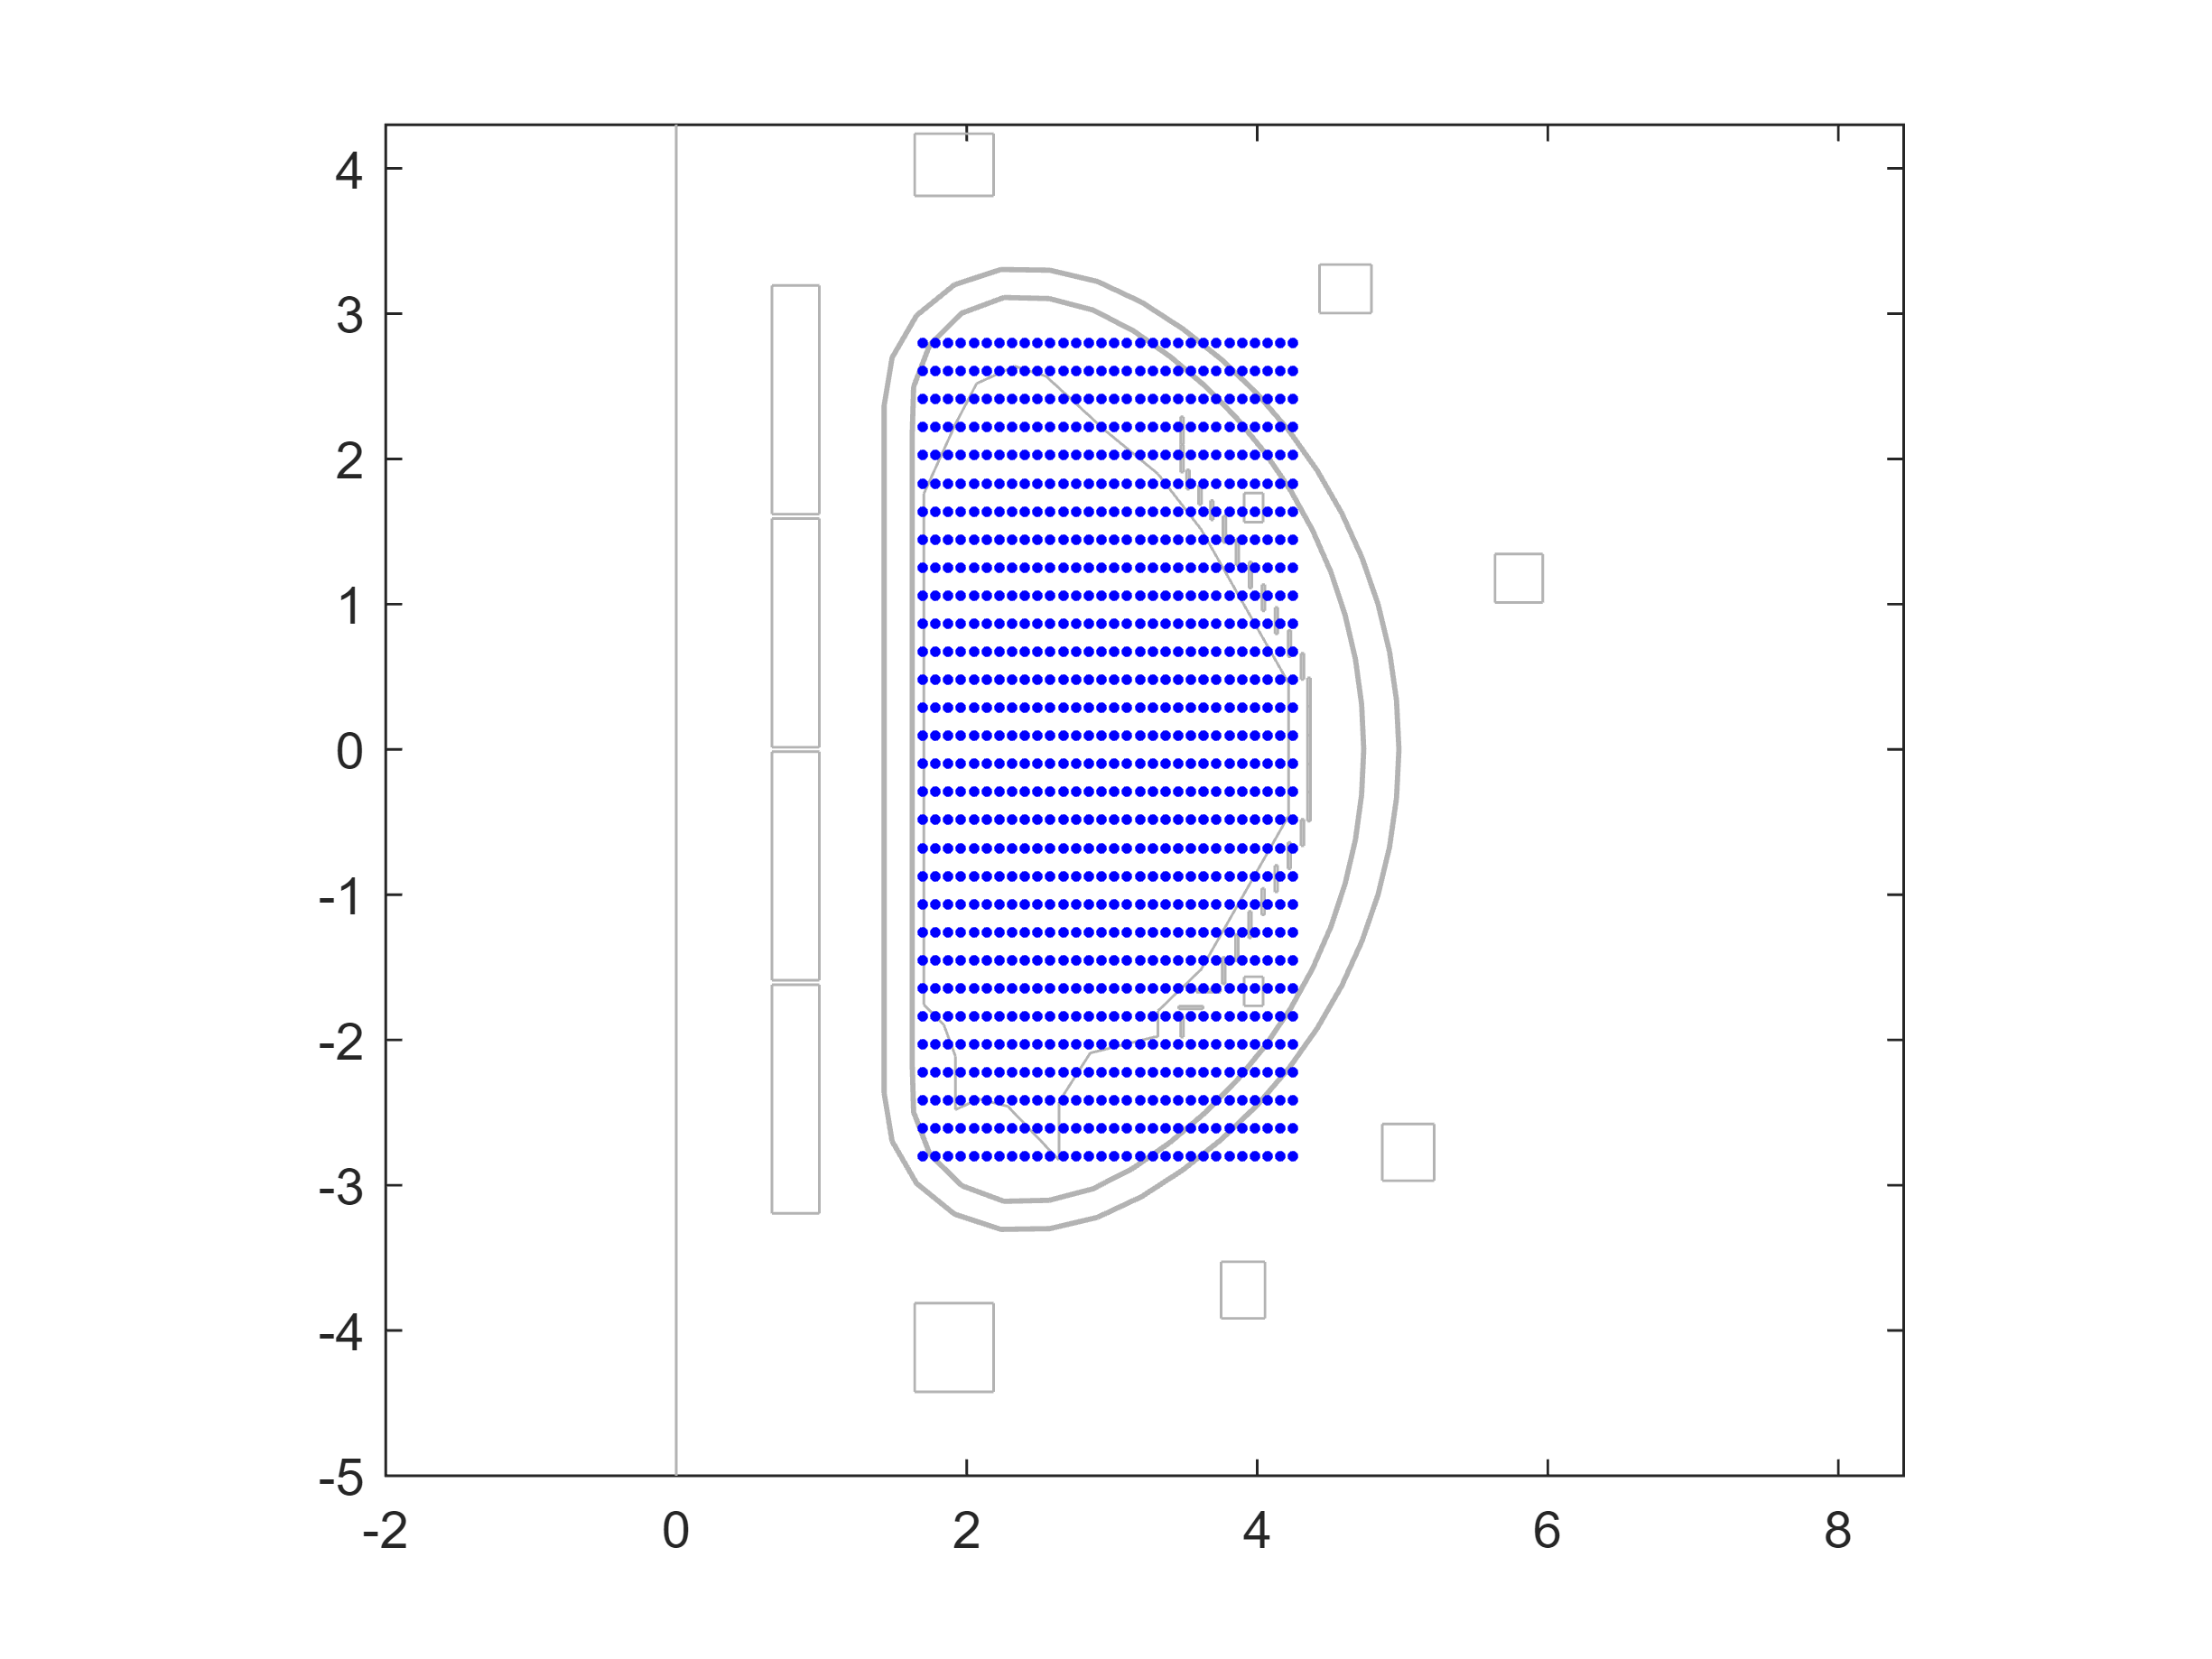

i_fg = get_y_idx(model.y_type,'Flux_grid');
n_fg = model.y_type(i_fg,1);
r_fg = model.Input_struct.r_sens(contains(model.Input_struct.names_sensors,n_fg));
z_fg = model.Input_struct.z_sens(contains(model.Input_struct.names_sensors,n_fg));

figure;
plot_mesh(model.Input_struct);
hold on
plot(r_fg,z_fg,'.b')
xlim([-2.00 8.45])
ylim([-5.00 4.30])

We can look at a contour-plot the equilibrium values of these virtual measurements as follows

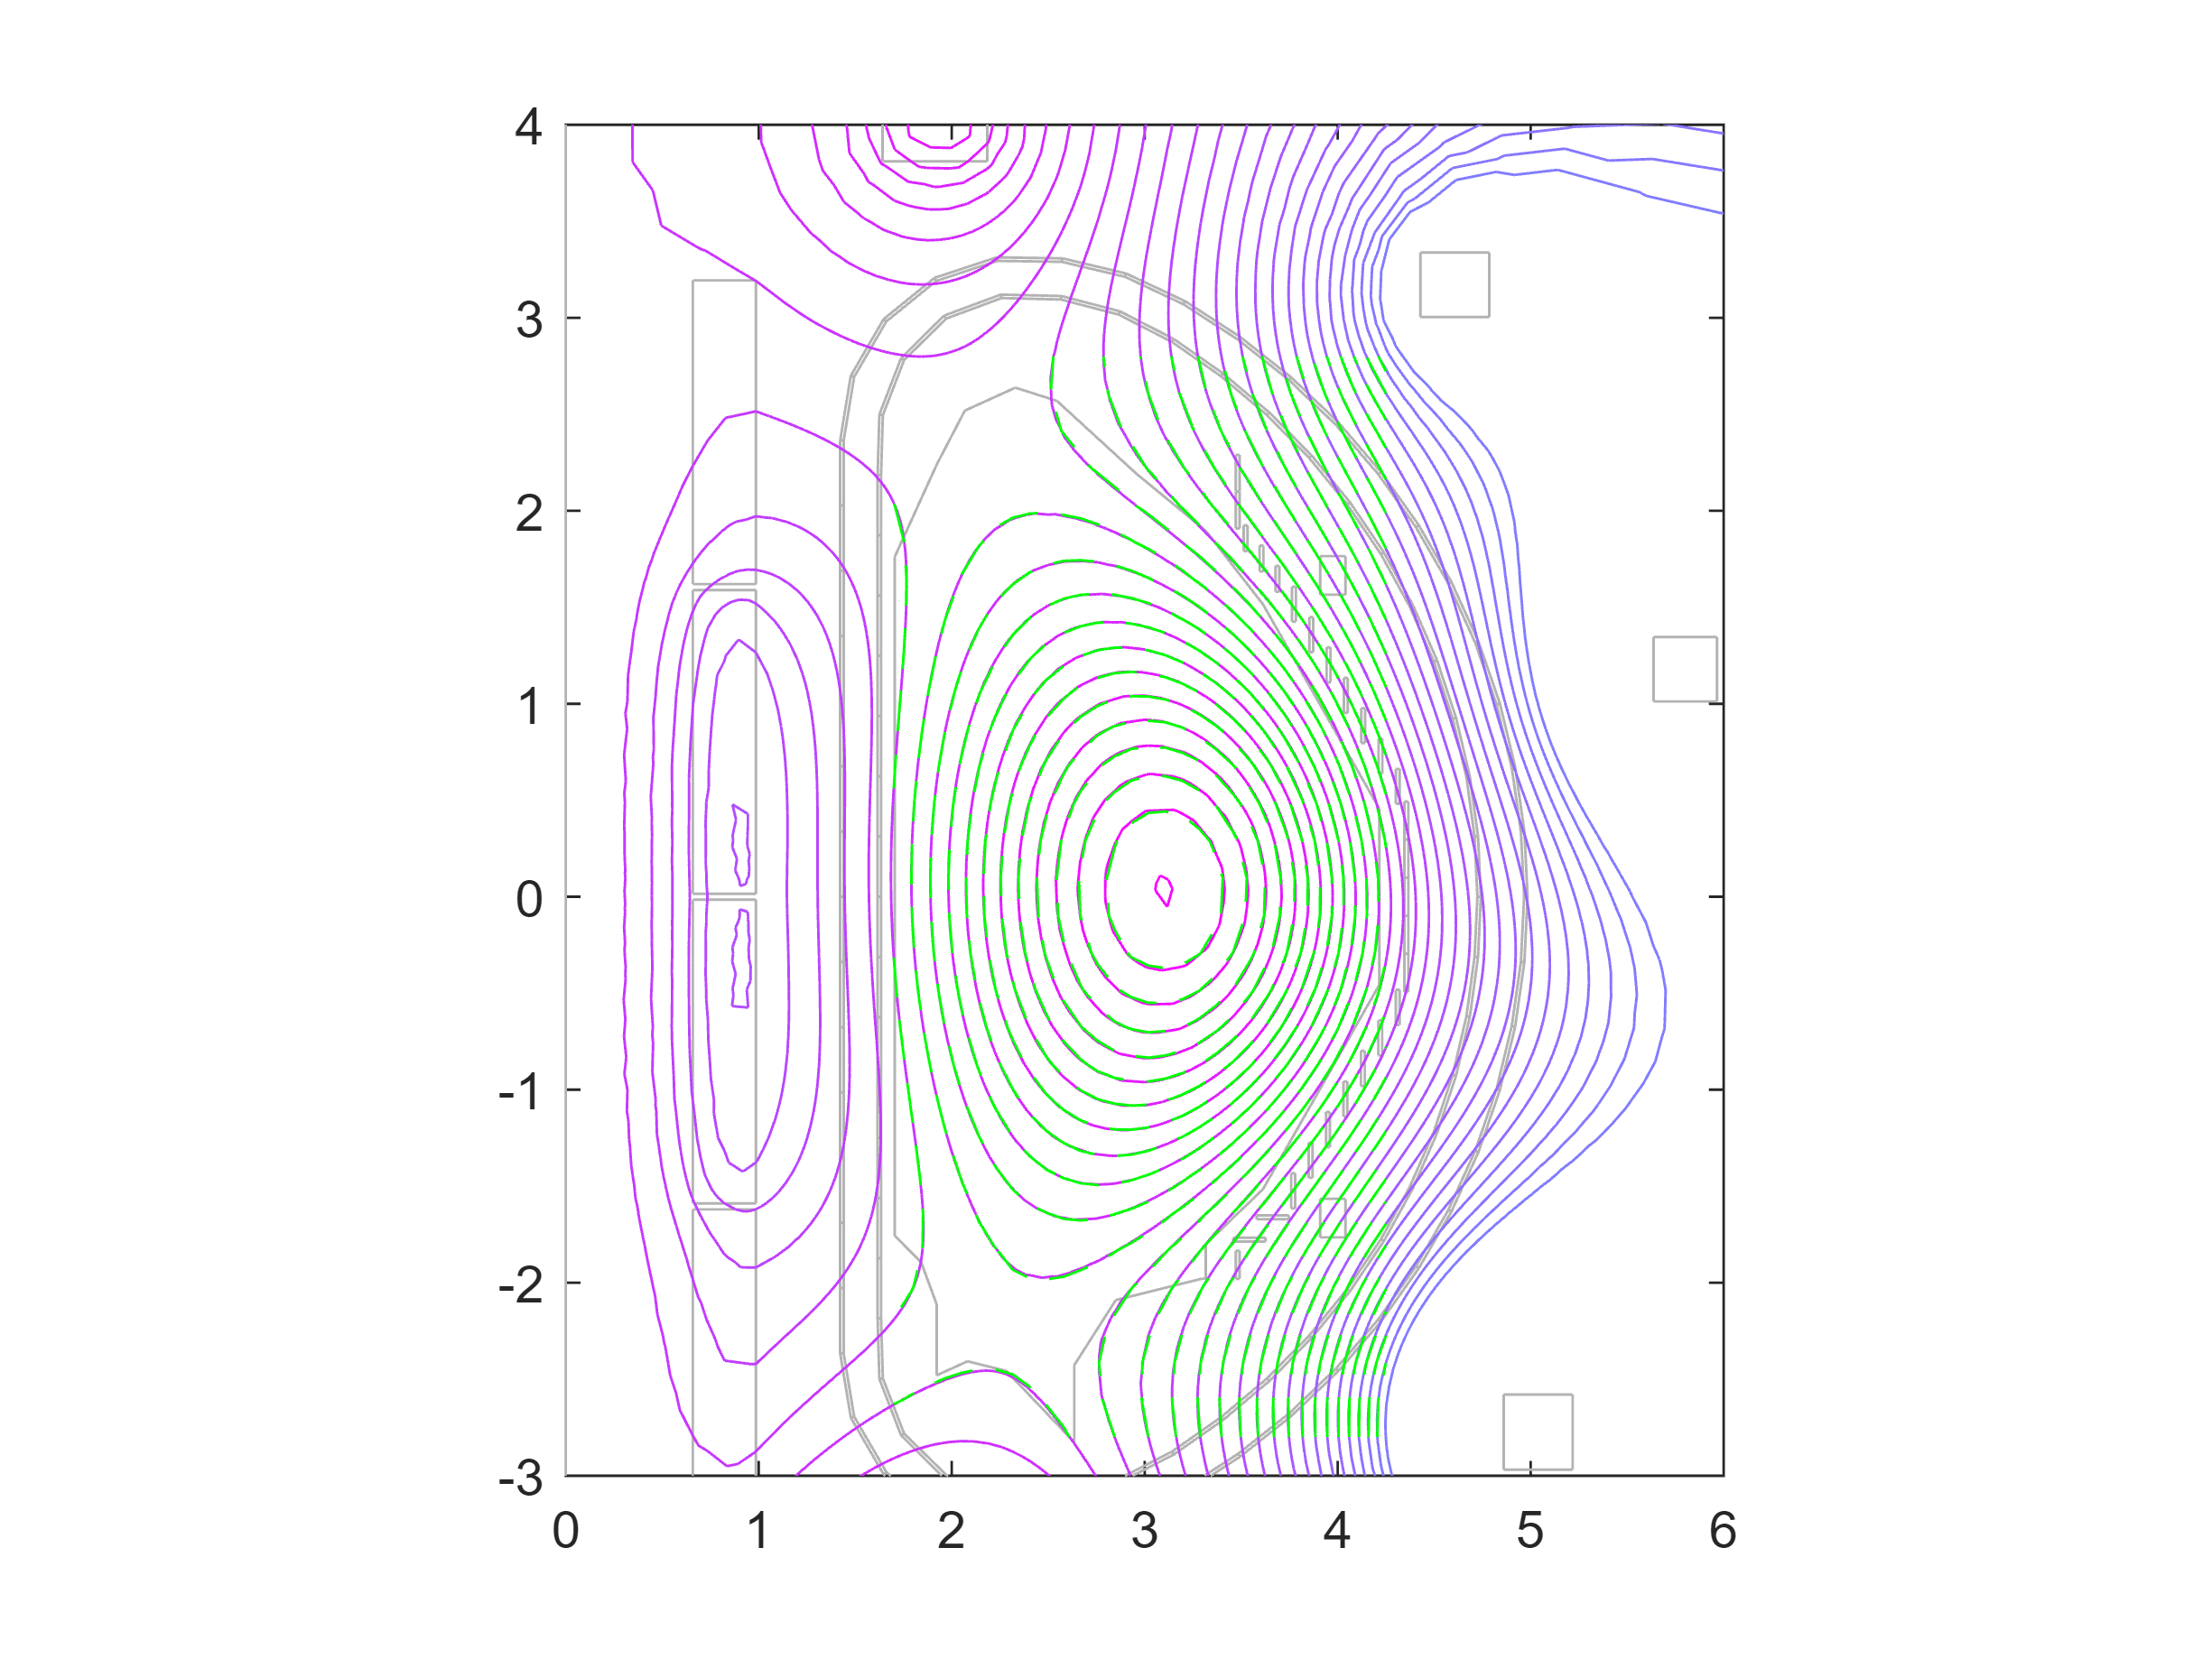

eq_fg = model.y_np(i_fg);  % equilibrium values of the virtual sensors (notice that there is a factor 2pi between the sensors and the GS solution)

R_fg = reshape(r_fg,30,30); % reshape into a matrix
Z_fg = reshape(z_fg,30,30);
E_fg = reshape(eq_fg,30,30);

figure;
plot_mesh(model.Input_struct);
hold on
plot_plasma(model.Input_struct, psieq, linspace(min(eq_fg/2/pi),max(eq_fg/2/pi),30));
hold on
contour(R_fg,Z_fg,E_fg,linspace(min(eq_fg),max(eq_fg),30),'g--')
xlim([0 6])
ylim([-3 4])

Here are the equilibrium PF currents

I_PF = model.y_np(1:10);
table(I_PF,'RowNames',model.y_type(1:10,1))

ans = 10×1 table
            I_PF  
           _______

    CS1    -1399.7
    CS2     -12059
    CS3     -11927
    CS4    -3903.5
    EF1     -12061
    EF2     -10328
    EF3     8339.7
    EF4      10474
    EF5     2451.8
    EF6     -17448


and the values of $\beta_p$, $l_i$, $I_p$

i_Ip = get_y_idx(model.y_type,'Ipl',1);
i_bp = get_y_idx(model.y_type,'betapol',1);
i_li = get_y_idx(model.y_type,'li',1);

table([model.y_np(i_Ip),model.y_np(i_bp),model.y_np(i_li)]','RowNames',{'Ipl','beta_p','l_i'},'VariableNames',{'plasma parameters'})

ans = 3×1 table
              plasma parameters
              _________________

    Ipl            5.5e+06     
    beta_p         0.52957     
    l_i             0.8494     


Let's see the effect on the flux map of decreasing the current in EF1 of 500A. First, extract the rows of the C matrix associated to our virtual flux probes and to the boundary flux

C_fg  = model.C(i_fg,:);
C_psb = model.C(i_psb,:);

then define a current variation on the 5th circuit (EF1)

dI    = zeros(size(model.C,2),1);
dI(5) = -500;

and finally compute the outputs variation as $\delta y = C\delta I$

dy = C_fg*dI;
dY = reshape(dy,30,30);
dpsib = C_psb*dI;

Let's check the result of this operation

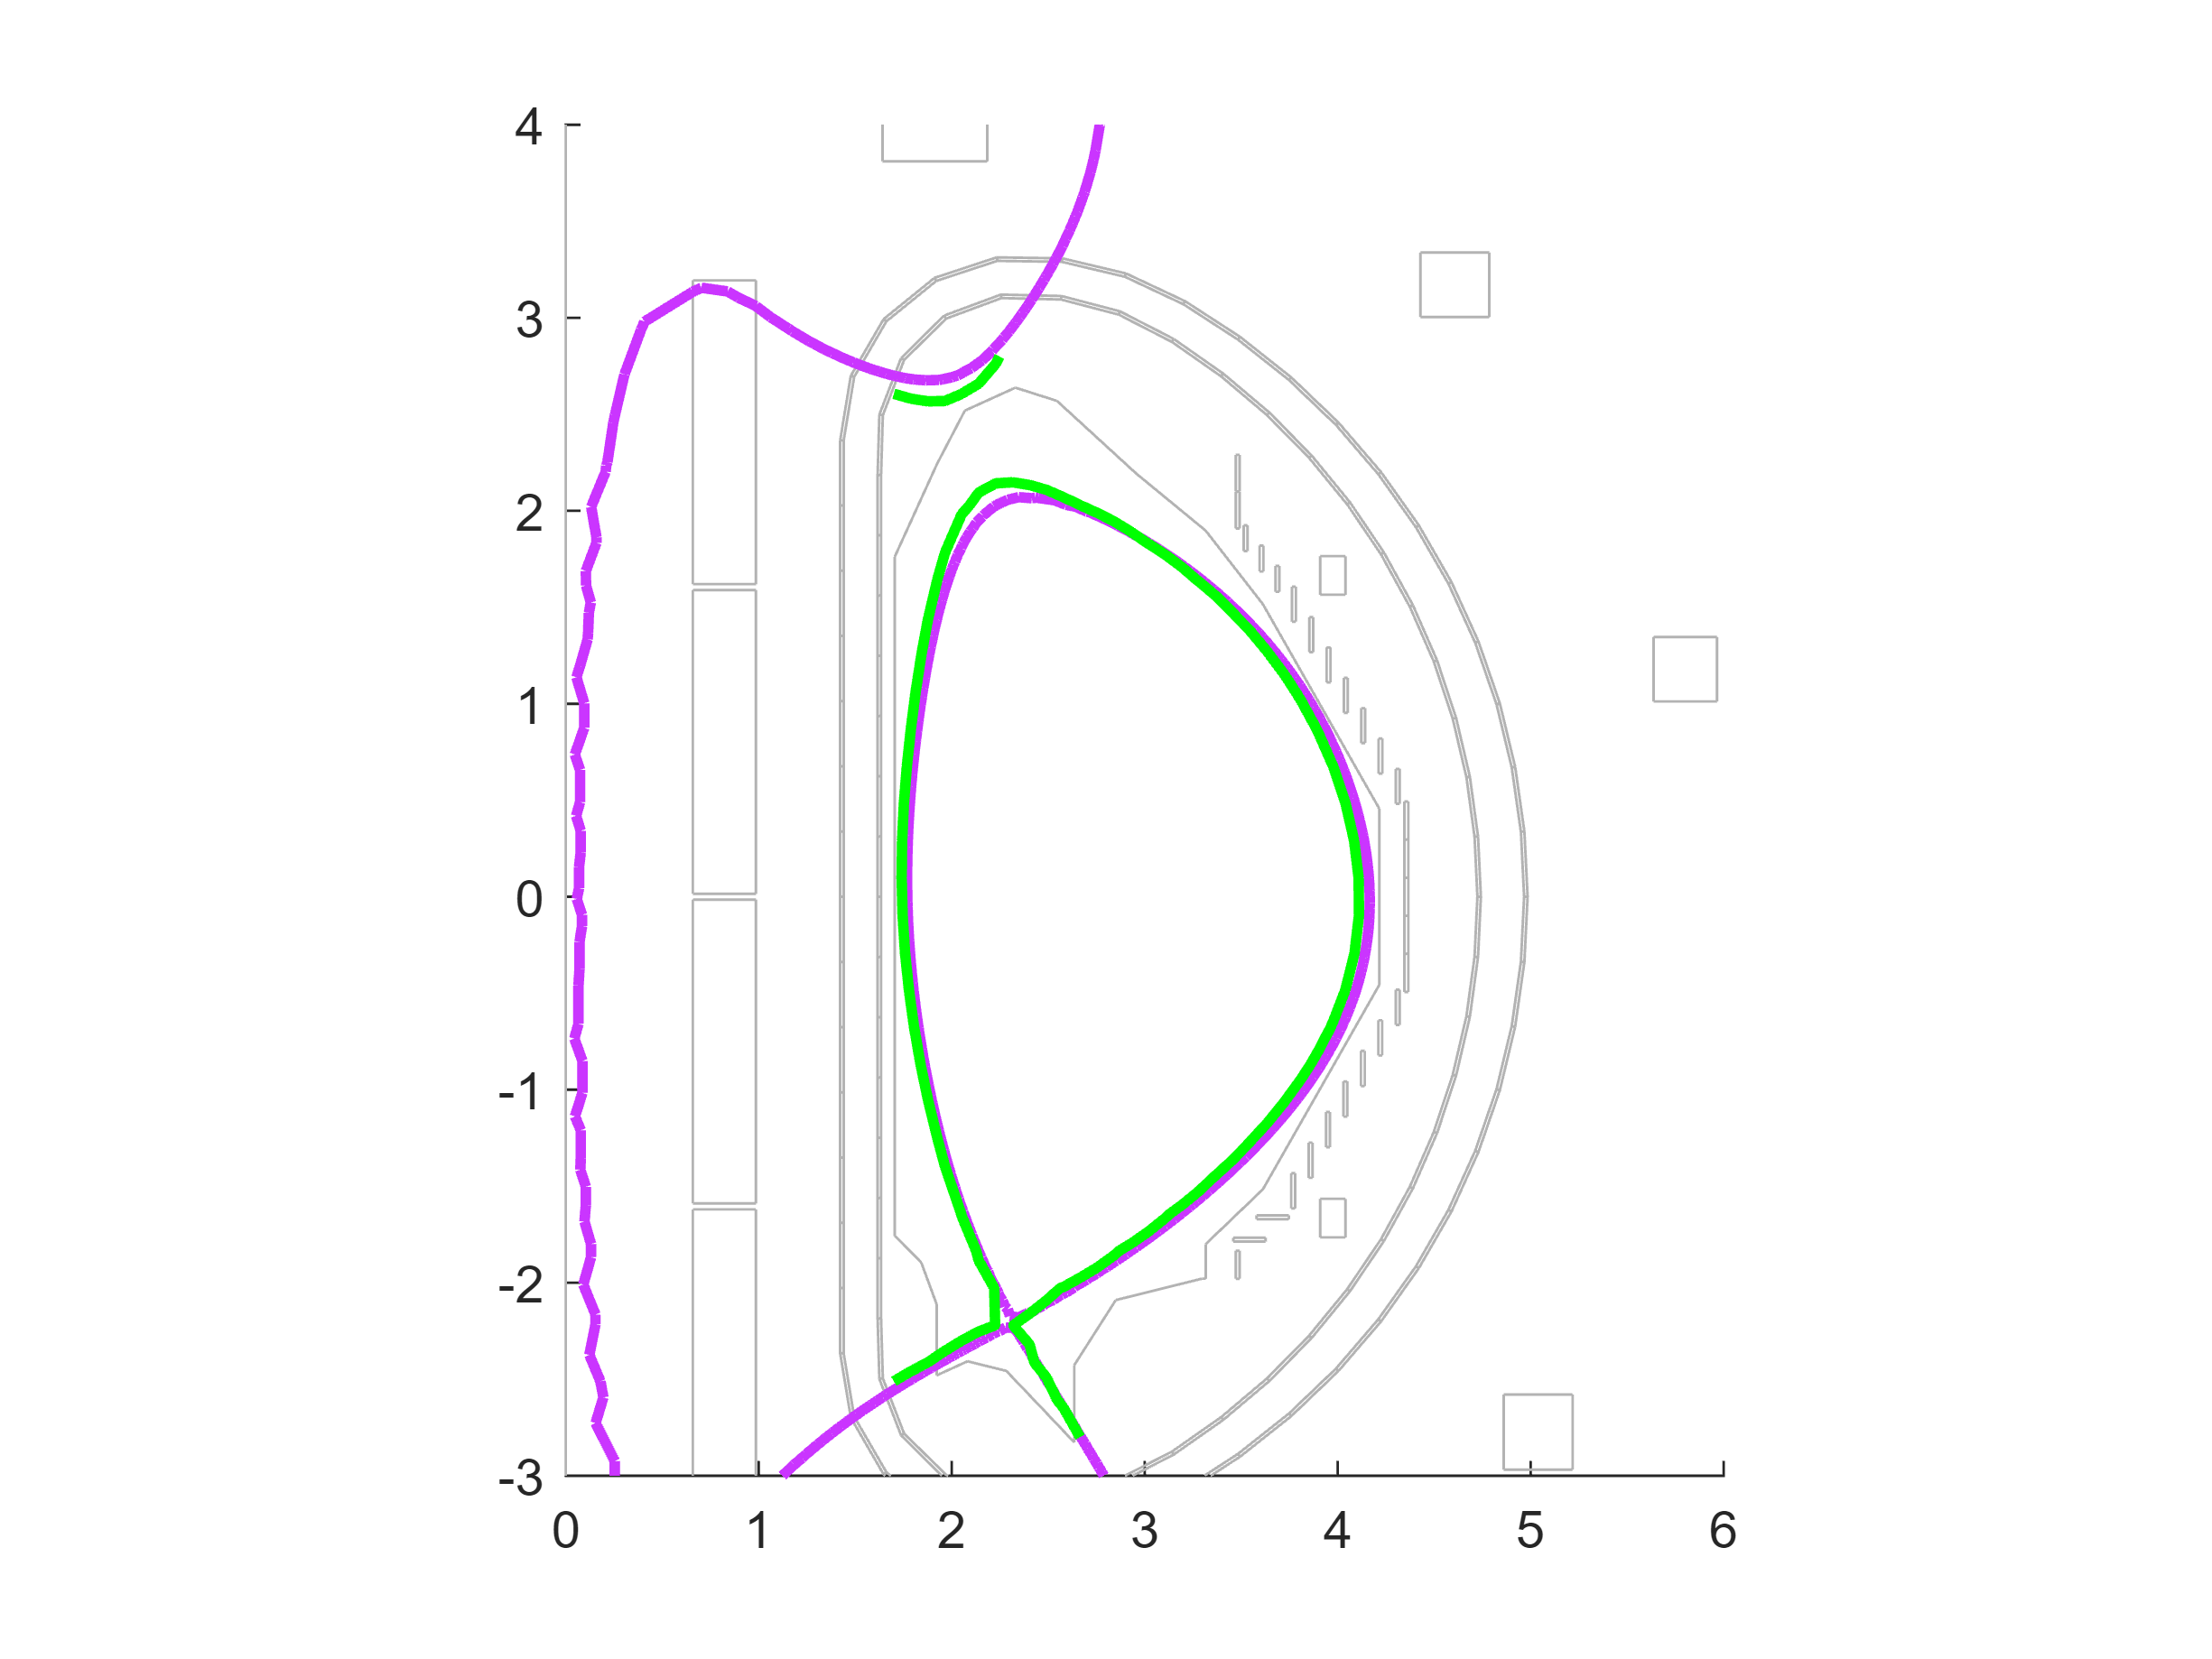

figure;
hold on
plot_mesh(model.Input_struct);
hb = plot_plasma(model.Input_struct, psieq, psib*[1 1]);
set(hb,'linewidth',2)
hold on
contour(R_fg,Z_fg,E_fg+dY,(psib+dpsib)*2*pi*[1 1],'g','linewidth',2) % 2 pi is needed to go back to actual Wb
xlim([0 6])
ylim([-3 4])

We can evaluate the modification of the boundary also in terms of gap modifications. Start by getting the gaps definition and extracting the Radial Outer Gap (ROG)

% Get gaps definition
r_gap = model.Input_struct.r_sens_gap;
z_gap = model.Input_struct.z_sens_gap;
t_gap = model.Input_struct.theta_sens_gap_deg;

% Find outer radial gap
[rg,iROG] = max(r_gap);
zg = z_gap(iROG);
tg = t_gap(iROG);
lg = 1; % gap length

We can do the same plot as before

figure;
hb = plot_plasma(model.Input_struct, psieq, psib*[1 1]);
set(hb,'linewidth',2)
hold on
contour(R_fg,Z_fg,E_fg+dY,(psib+dpsib)*2*pi*[1 1],'g','linewidth',2)
xlim([0 6])
ylim([-3 4])

and then add the gaps to the plot as follows

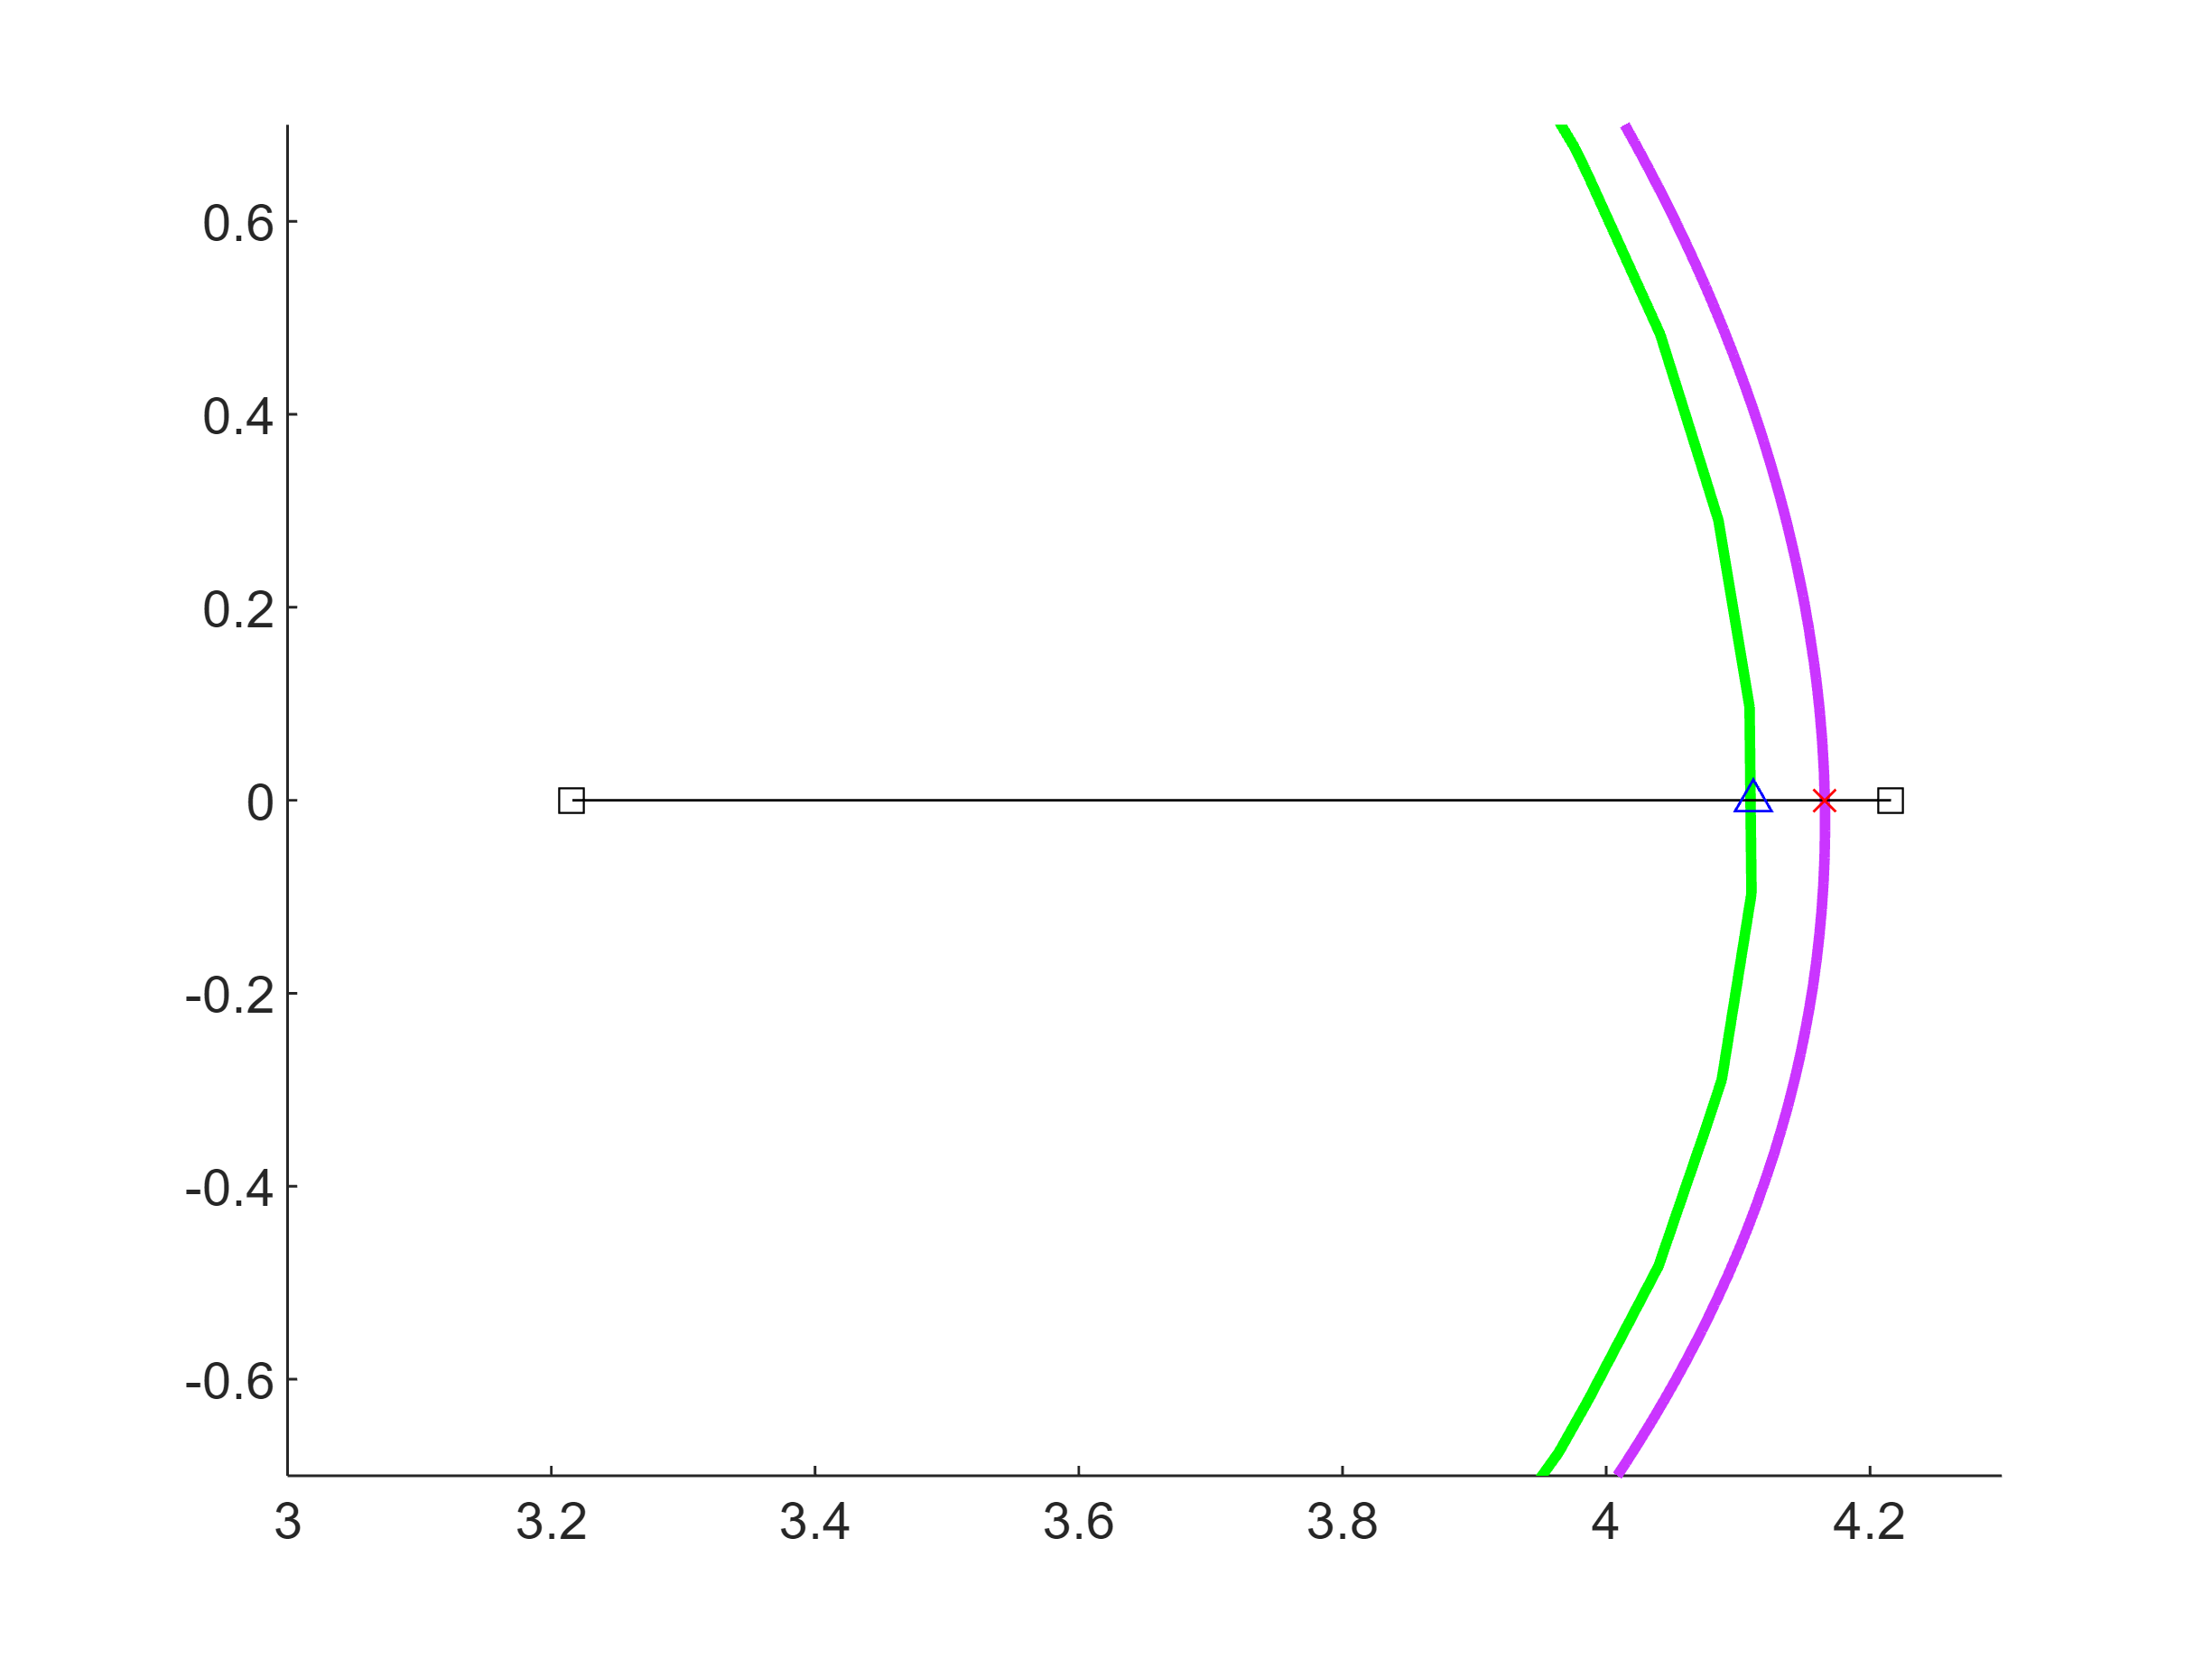

plot([rg rg+lg*cosd(tg)], [zg zg+lg*sind(tg)],'sk-')

% Find equilibrium gap value
i_gap = get_y_idx(model.y_type,'Gap');
i_gap = i_gap(iROG);
ROG_eq = model.y_np(i_gap);

% Compute gap modification
C_gap = model.C(i_gap,:);
dROG  = C_gap*dI;

% Plot results
plot(rg+ROG_eq*cosd(tg), zg+ROG_eq*sind(tg),'xr') % equilibrium
plot(rg+(ROG_eq+dROG)*cosd(tg), zg+(ROG_eq+dROG)*sind(tg),'^b') % modified
xlim([3 4.3])
ylim([-0.7 0.7])